# **R-factor: link of 4D seismic and PDA**

## Introduction

**Authors**: Ivan Abakumov

**Publication date**: 28th of October 2019

**E-mail**: ivan.abakumov@fu-berlin.de

clear; close all; clc;
mlibfolder = '/home/ivan/Desktop/MLIB';
path(path, mlibfolder);
add_mlib_path;

## Load G-file and comsol data

% Model 7 - the last one
Results = MLD('/home/ivan/Desktop/Comsol/My_model_7_results.mat');
G = MLD('/home/ivan/Desktop/Comsol/My_model_7_G_file.mat');
Model = MLD('/home/ivan/Desktop/MLIB/Examples/R_factor/Model5.mat');

% stress < 0 
% pressure > 0

sigma_x = (-Results.stress_x(:,:,end) -  Results.pressure(:,:,end)) - ...
          (-Results.stress_x(:,:,1) - Results.pressure(:,:,1));

      
sigma_y = (-Results.stress_y(:,:,end) - Results.pressure(:,:,end)) - ...
          (-Results.stress_y(:,:,1) - Results.pressure(:,:,1));        

sigma.x = sigma_x/1e6; 
sigma.z = sigma_y/1e6; 
      


phi_c1 = 0.006;
phi_c2 = 0.006;
phi_c3 = 0.008;
Fc = 0.037;
F1 = 0.0022;
F2 = 0;
F3 = -0.0004;


Anomaly.Vp = zeros(G.nx, G.nz);
Anomaly.Vs = zeros(G.nx, G.nz);
Anomaly.del = zeros(G.nx, G.nz);
Anomaly.eps = zeros(G.nx, G.nz);
Anomaly.gam = zeros(G.nx, G.nz);


for i = 1:1:G.nx
    for j = 1:1:G.nz

        C11 = Model.Vp(i,j)^2*Model.rho(i,j)/1e9;
        C66 = Model.Vs(i,j)^2*Model.rho(i,j)/1e9;
        C12 = C11 - 2*C66; 
        
        Sx = -sigma.x(i,j);
        Sz = -sigma.z(i,j);

        

        C0 = [C11 C12 C12 0   0   0; ...
              C12 C11 C12 0   0   0; ...
              C12 C12 C11 0   0   0; ...
              0   0   0   C66 0   0; ...
              0   0   0   0   C66 0; ...
              0   0   0   0   0   C66];
          
        S0 = inv(C0);

        fc10 = phi_c1; 
        fc20 = phi_c2; 
        fc30 = phi_c3; 
    
        fc1 = phi_c1*exp(Fc*Sx); 
        fc2 = phi_c2*exp(Fc*Sx); 
        fc3 = phi_c3*exp(Fc*Sz); 
    
        fs1 = S0(1,1)*Sx + S0(1,2)*Sx + S0(1,3)*Sz;
        fs2 = S0(1,2)*Sx + S0(2,2)*Sx + S0(2,3)*Sz;
        fs3 = S0(1,3)*Sx + S0(2,3)*Sx + S0(3,3)*Sz;
    
        dSc0 = [fc10    0       0       0       0       0; ...
               0      fc20     0       0       0       0; ...
               0      0       fc30     0       0       0; ...
               0      0       0       fc20+fc30 0       0; ...
               0      0       0       0       fc10+fc30 0; ...
               0      0       0       0       0       fc10+fc20]; 
    
        dSc = [fc1    0       0       0       0       0; ...
               0      fc2     0       0       0       0; ...
               0      0       fc3     0       0       0; ...
               0      0       0       fc2+fc3 0       0; ...
               0      0       0       0       fc1+fc3 0; ...
               0      0       0       0       0       fc1+fc2]; 
    
         dSs1 = [fs1    0       0       0       0       0; ...
                 0      fs2     0       0       0       0; ...
                 0      0       fs3     0       0       0; ...
                 0      0       0       fs2+fs3 0       0; ...
                 0      0       0       0       fs1+fs3 0; ...
                 0      0       0       0       0       fs1+fs2]; 
    
         dSs2 = [fs2+fs3 fs1+fs2 fs1+fs3 0      0       0; ...
                 fs1+fs2 fs1+fs3 fs2+fs3 0      0       0; ...
                 fs1+fs3 fs2+fs3 fs1+fs2 0      0       0; ...
                 0       0       0       2*fs1-fs2-fs3  0   0; ...
                 0       0       0       0      2*fs2-fs1-fs3    0; ...
                 0       0       0       0      0       2*fs3-fs1-fs2];
      
        dSs3 =  [0      fs3     fs2     0       0       0; ...
                 fs3    0       fs1     0       0       0; ...
                 fs2    fs1     0       0       0       0; ...
                 0      0       0      -2*fs1   0       0; ...
                 0      0       0       0      -2*fs2   0; ...
                 0      0       0       0       0      -2*fs3];
   
        S = S0 - Fc*dSc0 + Fc*dSc + F1*dSs1 + F2*dSs2 + F3*dSs3; 
        
        C = inv(S);
        
        alpha = sqrt(C(1,1)*1e9/Model.rho(i,j));
        beta  = sqrt(C(4,4)*1e9/Model.rho(i,j));
        eps = (C(1,1) - C(3,3))/(2*C(3,3));
        gam = (C(6,6) - C(4,4))/(2*C(4,4));
        del = ((C(1,3) + C(4,4))^2 - (C(3,3) - C(4,4)).^2)/(2*C(3,3)*(C(3,3) - C(4,4)));
        
        Anomaly.alpha(i,j) = alpha; 
        Anomaly.beta(i,j) = beta; 
        Anomaly.del(i,j) = eps;
        Anomaly.eps(i,j) = gam;
        Anomaly.gam(i,j) = del; 
        
        
        
    end
end
         


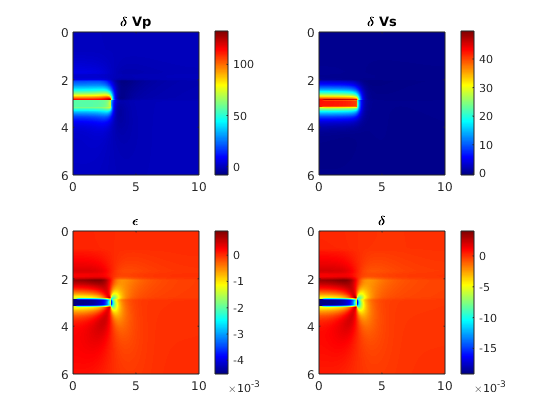

figure(23)
subplot(2,2,1)
imagesc(G.xx/1e3, G.zz/1e3, Anomaly.alpha' - Model.Vp')
title('\delta Vp')
colorbar; 
subplot(2,2,2)
imagesc(G.xx/1e3, G.zz/1e3, Anomaly.beta' - Model.Vs')
title('\delta Vs')
colorbar; 
subplot(2,2,3)
imagesc(G.xx/1e3, G.zz/1e3, Anomaly.eps')
title('\epsilon')
colorbar; 
subplot(2,2,4)
imagesc(G.xx/1e3, G.zz/1e3, Anomaly.del')
title('\delta')
colorbar; 
colormap('jet')

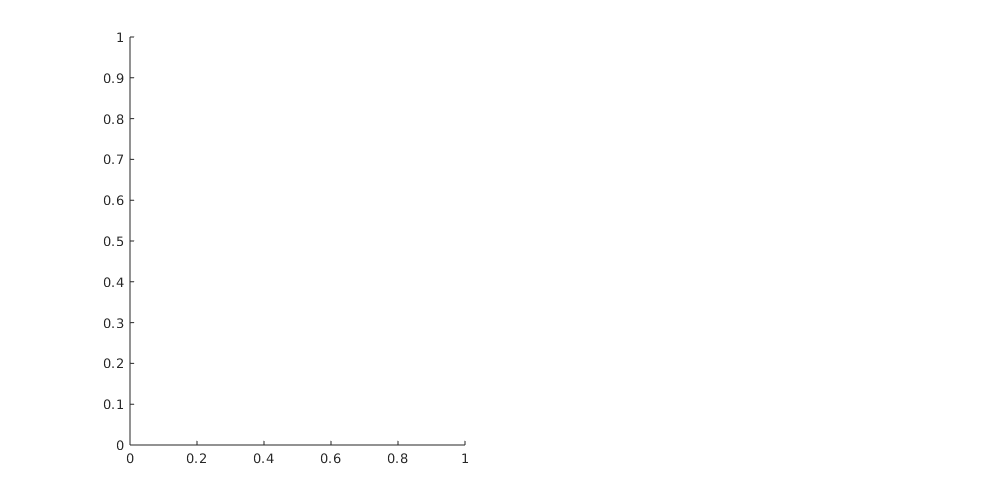


figure(98)
fig = figure('Position', [1 1 1000 500]);
subplot(1,2,1)

imagesc(G.xx/1e3, G.zz/1e3, dvelmod')

Unrecognized function or variable 'dvelmod'.

hold on 
rectangle('Position', [0.0,2.85,3,0.3], 'LineStyle',  '-', 'LineWidth',1)
plot(linspace(0,10,100), linspace(800,800,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(1750,1750,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(1750,1750,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(2000,2000,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(2850,2850,100)/1e3, '--k', 'LineWidth',1)
colormap(makeColorMap([0 0 1],[1 1 1],[1 0 0],100));
caxis([-50 50])
colorbar
xlabel('Distance [km]')
ylabel('Depth [km]')
title('Changes in P-wave velocity [m/s]')
text(-3, 0, 'a)', 'FontSize', 16) 


subplot(1,2,2)
imagesc(G.xx/1e3, G.zz/1e3, 1000*dtti')
hold on 
rectangle('Position', [0.0,2.85,3,0.3], 'LineStyle',  '-', 'LineWidth',1)
plot(linspace(0,10,100), linspace(800,800,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(1750,1750,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(1750,1750,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(2000,2000,100)/1e3, '--k', 'LineWidth',1)
plot(linspace(0,10,100), linspace(2850,2850,100)/1e3, '--k', 'LineWidth',1)
colormap(makeColorMap([0 0 1],[1 1 1],[1 0 0],100));
caxis([-2 2])
colorbar
title('Timeshift [ms]')

xlabel('Distance [km]')
ylabel('Depth [km]')
text(-3, 0, 'b)', 'FontSize', 16) 